**Discussion HW 4**

Steven Henderson

**3 Introduction**

We are looking at the wheel with two masses, as shown in slide7 of the Discussion slides. Use the following parameters: the mass of the wheel is m`w` = 1.29 kg; R = 31 cm; M = 0.3 kg.

**4 Do This**

(A) Make a single plot of the normalized potential energy u = U/(M gR) as a function of θ for mass ratios μ = m/M = (0.7, 0.8, 1.1) and m`w` = 0. Make sure the three curves, one for each μ are clearly distinguishable and labeled.

Defining potential = 0 at the top of the wheel.


$$\begin{array}{l}
V_M =-\mathrm{Mg}\left(R+\mathrm{Rcos}\phi \right)\\
V_m =-\mathrm{mg}\left(R+R\phi \right)\\
V_w ={-m}_w \mathrm{gR}\\
V=-\mathrm{MgR}\left(1+\cos \phi \right)-\mathrm{mgR}\left(1+\phi \right)-m_w \mathrm{gR},m_w =0\\
u=\frac{V}{\mathrm{MgR}}=-1-\cos \phi -\mu \left(1+\phi \right)
\end{array}$$


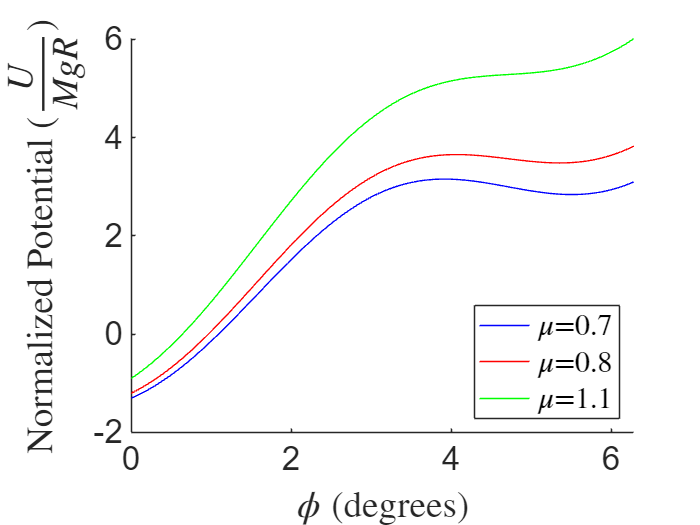

% Initial variables
mu = [0.7, 0.8, 1.1] ;
phispan = deg2rad(linspace(0, 360, 1000)) ;
% Find normalized potential energy
u_07 = - 1 - cos(phispan) + mu(1)*(1 + phispan) ;
u_08 = - 1 - cos(phispan) + mu(2)*(1 + phispan) ;
u_11 = - 1 - cos(phispan) + mu(3)*(1 + phispan) ;
% Plot normalized poetentials vs. phi
clf
hold on
plot(phispan, u_07, 'b')
plot(phispan, u_08, 'r')
plot(phispan, u_11, 'g')
hold off
legend('$\mu$=0.7', '$\mu$=0.8', '$\mu$=1.1', 'Interpreter', 'latex', 'Location', 'southeast')
ylabel('Normalized Potential ($\frac{U}{MgR}$)', 'Interpreter', 'latex')
xlabel('$\phi$ (degrees)', 'Interpreter', 'latex')
set(gca, 'Fontsize', 20)

(B) For each μ, find the angles of equilibrium with m`w` = 0, if any. Are they stable or unstable equilibria. Do these angles of equilibria change if you assume that the wheel has mass m`w` 6 = 0? If they do, give the new angles. Do these angles change as a function of the initial conditions, namely, the angle and angular speed at the moment of release (t = 0)

For Equilibirum potenial energy slope should equal 0 meaning no change in potential and therefore no change in position.


$$\begin{array}{l}
\frac{\mathrm{dV}}{d\phi }=\frac{d}{d\phi }\left(-\mathrm{MgR}\left(1+\cos \phi \right)-\mathrm{mgR}\left(1+\phi \right)-m_w \mathrm{gR}\right)=\mathrm{MgRsin}\phi -\mathrm{mgR}\\
m=M\mu 
\end{array}$$


% Function for getting dV/dphi for different mus and phispan
% returns array
function out = dVdphi(mu, phispan)
   % Initial variables
    M = 0.3 ;
    g = 10 ;
    R = 0.31 ; 
    out = M*g*R*sin(phispan) - M*mu*g*R ;
end
func_07 = dVdphi(mu(1), phispan) ;
func_08 = dVdphi(mu(2), phispan) ;
func_11 = dVdphi(mu(3), phispan) ;

% Function to check where an array crosses the x-axis
function indicies = crossx(array)
    indicies = [] ;
    for i = 1:length(array) - 1
        if (array(i) > 0 && array(i + 1) < 0) || (array(i) < 0 && array(i + 1) > 0)
            indicies(end + 1) = i ;
        end
    end
end

% Function for getting values from an array with an array
function values = getVals(input_array, indicies)
    values = [] ;
    for i = 1:length(indicies + 1)
        values(end + 1) = input_array(indicies(i)) ;
    end
end
intecepts_07 = getVals(phispan, crossx(func_07))

intecepts_07 =     0.7736    2.3648


intecepts_08 = getVals(phispan, crossx(func_08))

intecepts_08 =     0.9246    2.2139


intecepts_11 = getVals(phispan, crossx(func_11))


intecepts_11 =

     []



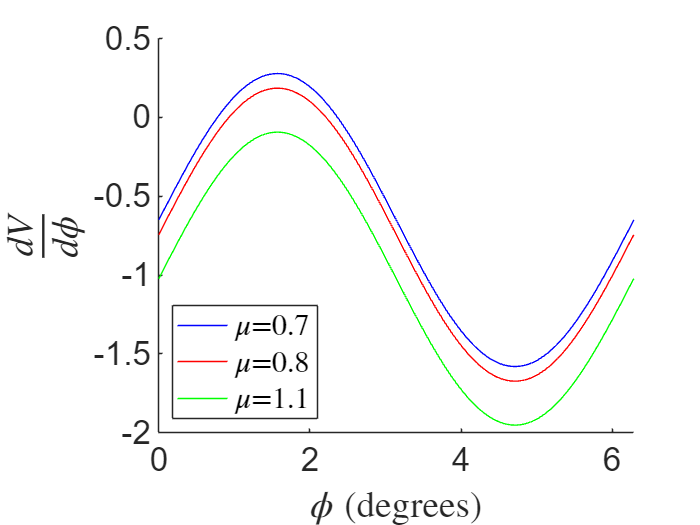


% Plot results
clf
hold on
plot(phispan, func_07, 'b') 
plot(phispan, func_08, 'r') 
plot(phispan, func_11, 'g') 
legend('$\mu$=0.7', '$\mu$=0.8', '$\mu$=1.1', 'Interpreter', 'latex', 'Location', 'southwest')
ylabel('$\frac{dV}{d\phi}$', 'Interpreter', 'latex')
xlabel('$\phi$ (degrees)', 'Interpreter', 'latex')
set(gca, 'Fontsize', 20)

(C) Derive the equation of motion (for an arbitrary μ) with m`w` = 0.


$$K=\frac{1}{2}{\textrm{mv}}^2 +\frac{1}{2}{\textrm{Mv}}^2 =\frac{1}{2}\left(m+M\right){\left(R\overset{\ldotp }{\phi} \right)}^2$$



$$\begin{array}{l}
V=-\textrm{MgR}\left(1+\cos \phi \right)-\textrm{mgR}\left(1+\phi \right)\\
L=K-U=\frac{1}{2}\left(m+M\right){\left(R\overset{\ldotp }{\phi} \right)}^2 V-\textrm{MgR}\left(1+\cos \phi \right)-\textrm{mgR}\left(1+\phi \right)\\
\frac{\partial L}{\partial \phi }=\textrm{MgRsin}\phi -\textrm{mgR}\\
\frac{\partial L}{\partial \overset{\ldotp }{\phi} }=\left(m+M\right)R^2 \overset{\ldotp }{\overset{\ldotp }{\phi} \to \frac{d}{\textrm{dt}}} \left(\frac{\partial L}{\partial \overset{\ldotp }{\phi} }\right)=\left(m+M\right)R^2 \overset{\ldotp \ldotp }{\phi} \\
\left(m+M\right)R^2 \overset{\ldotp \ldotp }{\phi} =\textrm{MgRsin}\phi -\textrm{mgR}\\
\overset{\ldotp \ldotp }{\phi} =\frac{\textrm{Mgsin}\phi }{R\left(m+M\right)}-\frac{\textrm{mg}}{R\left(m+M\right)}
\end{array}$$


(D) Find the frequency of small oscillations when μ = 0.8 (still with m`w` = 0).


$$\begin{array}{l}
\phi =\phi_{\textrm{eq}} +\zeta \left(t\right)\\
\overset{\ldotp }{\phi} =0\\
\overset{\ldotp \ldotp }{\phi} =0\\

\end{array}$$


(E) When you make observations you find that the frequency calculated in the previous section is not correct. Why? Fix the Lagrangian and the equation of motion and find a new frequency. (F) Optional (bonus 5 points) - the equation of motion can not be solved anlytically but it can be solved numerically. Write code to solve it exactly and give initial conditions such that the system executes small oscillations. Compare the exact numeric sollution to the pen-and-paper calculation.